This script will make the switching reverb stimulus. There is a 4s and an 8s version. The idea is to load the stimuli that were already created for the normal reverb stimulus and shuffle them around such that they alternate between reverb condition 1 (r1, small reverb) and reverb condition 2 (r2, big reverb) every 4 or 8 s. The data consists of the two reverb conditions r1 and r2 with two 40s stimuli each. According to the  chunk size the data is divided into 16 or 32 chunks taking the stimulus between 4 and 36s for each reverb condition and each stim. For the 8switch example, The numbering of the chunks is 1 = stim1(4s - 8s);2 = stim1(8s - 12s);... 8 = stim1(32s - 36s); 9 = stim2(4s - 8s); 10 = stim2(8s - 12s); ... 16 =  stim2(32s - 36s). The stimulus for r1 and r2 is made by first concatenating the truncated versions (4s-36s) of stim1 and stim2 and then extracting the chunks. So chunks 1-8 come from stim1 and chunks 9-16 come from stim2. Positions are defined in the following way: r1pos1 = the first little reverb epoch, immediately after r2pos2; r1pos2 = the second little reverb epoch, immediately after r1pos1 and before r2pos1; r2pos1 = the first big reverb epoch, immediately after r1pos2 and before r2pos2; r2pos2 = the second big reverb epoch, immediately after r2pos1 and before r1pos1;

**Parameters**

type = 'switch4'; %The type of stimuli, how often to switch between r1 and r2
begin_stim_s = 4; %The beginning of each stimulus in s
end_stim_s = 36; %The end of each stimulus in s
one_stim_s = end_stim_s - begin_stim_s; %The duration of one switching stim w/o the start epoch
total_stim_s = 2*(one_stim_s); %The duration of one cropped stimulus
db_target = 53; %What is the target dB for the two sounds
seed_no = 7; %The seed used to initialize the random number generator
num_start_pos = 16; %Number of starting positions for the first period
num_stim = 8; %Number of final stimuli
ramp_length_s = 0.2; %The length of the cosine ramp in s

** Find which stimuli don't have a noise burst**

folder_name = '/media/alex/4TB SSD/DATA/Freja_18_04_2018/reverb_with_noise_stimuli/';
metadata_path = [folder_name 'wav_files/alexreverbmetadata'];
load(metadata_path);
[num_rep,num_cond] = size(alexreverbmetadata);

for stim = 1:numel(alexreverbmetadata)
    noise_mat(stim) = alexreverbmetadata(stim).hasnoise;
end
noise_mat = reshape(noise_mat,num_rep,num_cond);
ix_nonoise_r1s1 = find(noise_mat(:,2) == 0);
ix_nonoise_r1s1 = [ix_nonoise_r1s1(1) 2];
ix_nonoise_r1s2 = find(noise_mat(:,5) == 0);
ix_nonoise_r1s2 = [ix_nonoise_r1s2(1) 5];
ix_nonoise_r2s1 = find(noise_mat(:,3) == 0);
ix_nonoise_r2s1 = [ix_nonoise_r2s1(1) 3];
ix_nonoise_r2s2 = find(noise_mat(:,6) == 0);
ix_nonoise_r2s2 = [ix_nonoise_r2s2(1) 6];

stim_names.r1{1} = alexreverbmetadata(ix_nonoise_r1s1(1),ix_nonoise_r1s1(2)).stimname;
stim_names.r1{2} = alexreverbmetadata(ix_nonoise_r1s2(1),ix_nonoise_r1s2(2)).stimname;
stim_names.r2{1} = alexreverbmetadata(ix_nonoise_r2s1(1),ix_nonoise_r2s1(2)).stimname;
stim_names.r2{2} = alexreverbmetadata(ix_nonoise_r2s2(1),ix_nonoise_r2s2(2)).stimname;

**Load, crop and normalize**

%Load all the stimuli
[r1s1_full,fs] = audioread(stim_names.r1{1});
r1s2_full = audioread(stim_names.r1{2});
r2s1_full = audioread(stim_names.r2{1});
r2s2_full = audioread(stim_names.r2{2});

%Crop the each stimulus between 4 and 36s i.e. a total of 32s per stimulus
r1s1_crop = r1s1_full(begin_stim_s*fs:end_stim_s*fs,:);
r1s2_crop = r1s2_full(begin_stim_s*fs:end_stim_s*fs,:);
r1_total_crop = [r1s1_crop;r1s2_crop];
r2s1_crop = r2s1_full(begin_stim_s*fs:end_stim_s*fs,:);
r2s2_crop = r2s2_full(begin_stim_s*fs:end_stim_s*fs,:);
r2_total_crop = [r2s1_crop;r2s2_crop];

%Normalize the sounds so that across both stimuli and ears dB(r1) = dB(r2);
dj_coeff_r1 = db_adjust(r1_total_crop(:),db_target);
dj_coeff_r2 = db_adjust(r2_total_crop(:),db_target);

r1_total_crop_norm = r1_total_crop.*dj_coeff_r1;
r2_total_crop_norm = r2_total_crop.*dj_coeff_r2;

db_r1_total = db_calc(r1_total_crop_norm(:)); %Calculate the final dB to double check levels for both reverb conditions
db_r2_total = db_calc(r2_total_crop_norm(:));

**Extract the sound chunks in a cell array**

switch type
    case 'switch8'
        chunk_size_s = 4; %Define chunk size
        num_chunks = total_stim_s/chunk_size_s;
        num_epochs = num_chunks/4; %epoch is one time period with two chunks in either r1 or r2 condition
        total_length_s = one_stim_s + 2*chunk_size_s; %Find the total length in s including both the start epoch and the switching epochs
        %Make a cosine ramp envelope
        env = cosrampenv(total_length_s,ramp_length_s,fs);
        env = env';
        env = repmat(env,1,2); %Copy for both ears
    case 'switch4'
        chunk_size_s = 2; %Define chunk size
        num_chunks = total_stim_s/chunk_size_s;
        num_epochs = num_chunks/4; %epoch is one time period with two chunks in either r1 or r2 condition
        total_length_s = one_stim_s + 2*chunk_size_s; %Find the total length in s including both the start epoch and the switching epochs
        %Make a cosine ramp envelope
        env = cosrampenv(total_length_s,ramp_length_s,fs);
        env = env';
        env = repmat(env,1,2);
end

%Define the indices of the chunks to be extracted
chunk_ix_s = [0:chunk_size_s:total_stim_s - chunk_size_s]; %Define the beginning of each chunk in seconds
chunk_ix_samples = chunk_ix_s*fs; %Convert to samples
chunk_ix_begin_samples = chunk_ix_samples + 1; %Add +1 to define properly the beginning of each chunk in samples
chunk_ix_end_samples =  chunk_ix_begin_samples + (chunk_size_s*fs - 1); %Define properly the end of each chunk

%Extract the chunks
for chunk_no = 1:num_chunks
    ix_start = chunk_ix_begin_samples(chunk_no);
    ix_end = chunk_ix_end_samples(chunk_no);
    r1_chunks{chunk_no} = r1_total_crop_norm(ix_start:ix_end,:);
    r2_chunks{chunk_no} = r2_total_crop_norm(ix_start:ix_end,:);
end

**Make random numbers**

%Make a randomised vectors for the starting positions + the 4 different
%reverb positions r1p1, r1p2, r2p1, r2p2

rng(seed_no); %Initialize with the same seed

rand_start = randperm(num_chunks,num_start_pos); %Pick the starting positions 
rand_start = reshape(rand_start,num_stim,2); %Reshape the random start 

%Pick random numbers for the four different positions in the stimuli
rand_r1pos1 = randperm(num_chunks,num_chunks);
rand_r1pos2 = randperm(num_chunks,num_chunks);
rand_r2pos1 = randperm(num_chunks,num_chunks);
rand_r2pos2 = randperm(num_chunks,num_chunks);


**Geenrate the switching stimuli**

Notes:

The idea is to have every chunk in all 4 positions (r1p1,r1p2,r2p1,r2p2), without repeating the same chunk in the same position (sampling without

replacement). The start chunks are drawn from random numbers between 1-16 without repeating. For the 8switch stim there are 5 epochs (1start, 2xr1 

and 2xr2)with 2 chunks of 4s per epoch. For the 4switch stim there are 9 epochs (1start, 4xr1 and 4xr2) with 2 chunks of 2s per epoch. The total 

length of stimuli is 40s (8s start + 32s switching) for '8switch' and 36s (4s start + 32s switching)for the '4switch'. In order to achive non-repeating 

stimuli, starting 1/2 stimuli in r1 and 1/2 in r2 we need 8 stimuli. Half of them start in r1 (4) and the other 1/2 in r2 (4). They then alternate 

between r1 and r2. The first four are mirror images of the last four i.e. when the first four are in r1 the last four in r2 and vice versa.

count_r1 = 0; %Counter variable for the r1 positions
count_r2 = 0; %Counter variable for the r2 positions
pos_vec = []; %Vector that stores the positions being used on every iteration 
current_data = []; %Temporary variable that stores the data to be added to the growing stimulus
start_data = []; %Temporary variable that stores the data to be added at the beginning of each stimulus
r2_start = cell(num_stim/2,1); %Cell aray that will hold the stimuli with r2 start
r1_start = cell(num_stim/2,1); %Cell aray that will hold the stimuli with r1 start

%Generate the first four switch stimuli that start from the r2 condition
for stim_no = 1:num_stim/2
    for epoch = 1:num_epochs 
        if mod(epoch,2) %Check if epoch number is odd or even. For odd treat it as r1 for even as r2
            count_r1 = count_r1 + 1;
            pos1 = rand_r1pos1(count_r1);
            pos2 = rand_r1pos2(count_r1);
            current_data = [r1_chunks{pos1};r1_chunks{pos2}]; %Store the r1 chunks corresponding to the random numbers in the temp var 
        else
            count_r2 = count_r2 + 1;
            pos1 = rand_r2pos1(count_r2);
            pos2 = rand_r2pos2(count_r2);
            current_data = [r2_chunks{pos1};r2_chunks{pos2}]; %Store the r2 chunks corresponding to the random numbers in the temp var 
        end
        pos_vec = [pos_vec,[pos1 pos2]]; %Store the chunk numbers and their positions for this stim
        r2_start{stim_no} = [r2_start{stim_no};current_data]; %Add the r1 or r2 epoch to the growing stimulus
    end
    pos1_start = rand_start(stim_no,1); %Find the starting position numbers
    pos2_start = rand_start(stim_no,2);
    start_data = [r2_chunks{pos1_start};r2_chunks{pos2_start}]; %Store the r2 chunks corresponding to the start of the stimulus
    r2_start{stim_no} = [start_data;r2_start{stim_no}]; %Add the start r2 data to the growing stim
    r2_start{stim_no} = r2_start{stim_no}.*env; %Apply the cosine ramp
    r2_start_matrix(stim_no,:) = [pos1_start,pos2_start,pos_vec]; %Save the positions of all the chunks
    pos_vec = [];
end

%Generate the last four switch stimuli that start from the r1 condition
pos_vec = [];
start_data = [];

for stim_no = 1:num_stim/2
    for epoch = 1:num_epochs %Check if epoch number is odd or even. For odd treat it as r2 for even as r1
        if mod(epoch,2)
            count_r2 = count_r2 + 1;
            pos1 = rand_r2pos1(count_r2);
            pos2 = rand_r2pos2(count_r2);
            current_data = [r2_chunks{pos1};r2_chunks{pos2}]; %Store the r2 chunks corresponding to the random numbers in the temp var 
        else
            count_r1 = count_r1 + 1;
            pos1 = rand_r1pos1(count_r1);
            pos2 = rand_r1pos2(count_r1);
            current_data = [r1_chunks{pos1};r1_chunks{pos2}]; %Store the r1 chunks corresponding to the random numbers in the temp var 
        end
        pos_vec = [pos_vec,[pos1 pos2]];
        r1_start{stim_no} = [r1_start{stim_no};current_data];
    end
    pos1_start = rand_start(stim_no + num_stim/2,1); %Find the starting position numbers
    pos2_start = rand_start(stim_no + num_stim/2,2);
    start_data = [r1_chunks{pos1_start};r1_chunks{pos2_start}]; %Store the r1 chunks corresponding to the start of the stimulus
    r1_start{stim_no} = [start_data;r1_start{stim_no}]; %Add the start r1 data to the growing stim
    r1_start{stim_no} = r1_start{stim_no}.*env; %Apply the cosine ramp
    r1_start_matrix(stim_no,:) = [pos1_start,pos2_start,pos_vec]; %Save the positions of all the chunks
    pos_vec = [];
end


**Plot and save all the data and metadata**

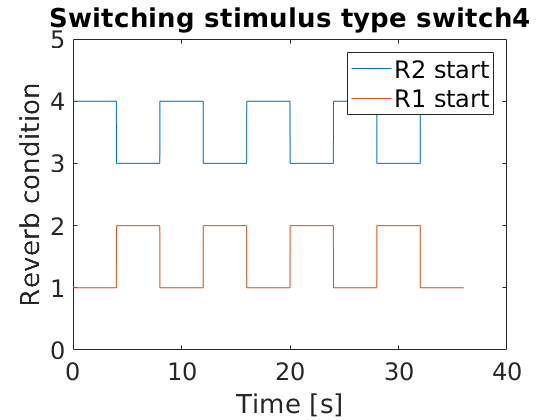

f_fs = 100; %Fake fs for plotting the switching stimulus
epoch_size = chunk_size_s*2;
switch_epoch_r2start = [ones(1,epoch_size*f_fs) 2*ones(1,epoch_size*f_fs)]; %Make vector of 1s and 2s corresponding to reveb conditions r1 and r2
plot_dat_r2start = repmat(switch_epoch_r2start,1,one_stim_s/(chunk_size_s*4));
plot_dat_r2start = [2*ones(1,epoch_size*f_fs) plot_dat_r2start];
switch_epoch_r1start = [2*ones(1,epoch_size*f_fs) ones(1,epoch_size*f_fs)]; %Make vector of 1s and 2s corresponding to reveb conditions r1 and r2
plot_dat_r1start = repmat(switch_epoch_r1start,1,one_stim_s/(chunk_size_s*4));
plot_dat_r1start = [ones(1,epoch_size*f_fs) plot_dat_r1start];
time_s = [1/f_fs:1/f_fs:total_length_s];
plot(time_s,plot_dat_r2start + 2);
hold on;
plot(time_s,plot_dat_r1start);
xlabel('Time [s]');
ylabel('Reverb condition');
title(['Switching stimulus type ' type]);
legend('R2 start','R1 start');
set(findall(gcf,'-property','FontSize'),'FontSize',18);
ylim([0 5]);


%Save the stimuli into wav files
for stim_no = 1:num_stim/2
    stimname_r2_start = ['wav_files/',type,'/',type,'_r2_start_',num2str(stim_no),'.wav'];
    switch_metadata.r2_start_stimnames{stim_no} = stimname_r2_start;
    audiowrite(stimname_r2_start,r2_start{stim_no},fs,'BitsPerSample',24);
    stimname_r1_start = ['wav_files/',type,'/',type,'_r1_start_',num2str(stim_no),'.wav'];
    switch_metadata.r1_start_stimnames{stim_no} = stimname_r1_start;
    audiowrite(stimname_r1_start,r1_start{stim_no},fs,'BitsPerSample',24);
end

%Save all the metadata
switch_metadata.stimuli_used = stim_names;
switch_metadata.num_stim = num_stim;
switch_metadata.stim_begin_s = begin_stim_s;
switch_metadata.stim_end_s = end_stim_s;
switch_metadata.random_seed = seed_no;
switch_metadata.stimulus_type = type;
switch_metadata.num_chunks = num_chunks;
switch_metadata.chunk_size_s = chunk_size_s;
switch_metadata.dB_target = db_target;
switch_metadata.dB_r1_total = db_r1_total;
switch_metadata.dB_r2_total = db_r2_total;
switch_metadata.cosine_ramp_length_s = total_length_s;
switch_metadata.cosine_ramping_time_s = ramp_length_s;
switch_metadata.fs = fs;
switch_metadata.r2_start_matrix = r2_start_matrix;
switch_metadata.r1_start_matrix = r1_start_matrix;
switch_metadata.plot_data.plot_dat_r2start = plot_dat_r2start;
switch_metadata.plot_data.plot_dat_r1start = plot_dat_r1start;
switch_metadata.plot_data.time_s = time_s;

save(['wav_files/',type,'/switch_metadata'],'switch_metadata');